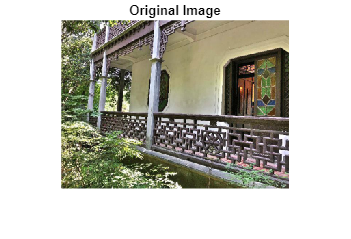

clc;
clear all
close all

% Section 1: File Selection and Preprocessing
startingFolder = pwd;  % or 'C:\wherever';
if ~isfolder(startingFolder)
    % If that folder doesn't exist, just start in the current folder.
    startingFolder = pwd;
end
% Get the name of the file that the user wants to use.
defaultFileName = fullfile(startingFolder, '*.*');
[baseFileName, folder] = uigetfile(defaultFileName, 'Select a file');
if baseFileName == 0
    % User clicked the Cancel button.
    return;
end

fullFileName = fullfile(folder, baseFileName);
theImage = imread(fullFileName);

% Section 2: Displaying Original Image and its HSV Components
im = imread(fullFileName);
figure, imshow(im), title('Original Image')

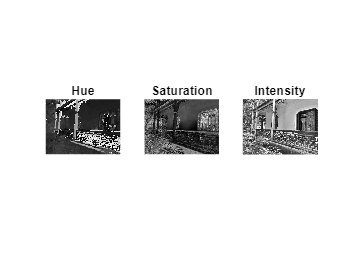

[row, col, ~] = size(im);

imhsv = rgb2hsv(im);
h1 = imhsv(:,:,1);
s1 = imhsv(:,:,2);
v1 = imhsv(:,:,3);
figure, subplot(1,3,1), imshow(h1), title('Hue')
subplot(1,3,2), imshow(s1), title('Saturation')
subplot(1,3,3), imshow(v1), title('Intensity')

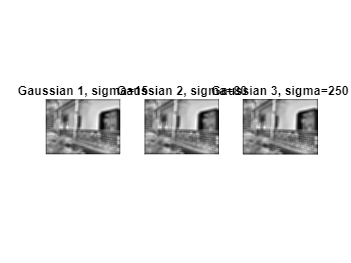


% Section 3: Applying Multiscale Gaussian Filtering
hsize = 15;
sigma1 = 15;
sigma2 = 80;
sigma3 = 250;

H1 = fspecial('gaussian', hsize, sigma1);
H2 = fspecial('gaussian', hsize, sigma2);
H3 = fspecial('gaussian', hsize, sigma3);

img1 = conv2(v1, H1, 'same');
img2 = conv2(v1, H2, 'same');
img3 = conv2(v1, H3, 'same');

% Section 4: Histogram Equalization and Fusion
figure
subplot(1,3,1), imshow(img1, []), title('Gaussian 1, sigma=15')
subplot(1,3,2), imshow(img2, []), title('Gaussian 2, sigma=80')
subplot(1,3,3), imshow(img3, []), title('Gaussian 3, sigma=250')

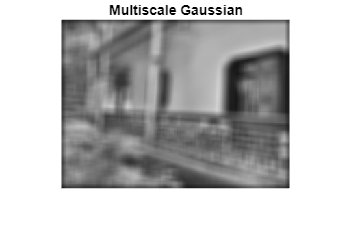


imggaus = 1/3 * img1 + 1/3 * img2 + 1/3 * img3;
figure, imshow(imggaus), title('Multiscale Gaussian')

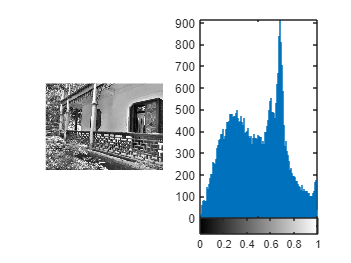


alpha1 = 0.9;
k1 = alpha1 * sum(s1(:)) / (row * col);
vnew1 = v1 * (1 + k1) ./ (max(v1, imggaus) + k1);
figure, subplot(1,2,1), imshow(v1);
subplot(1,2,2), imhist(v1)

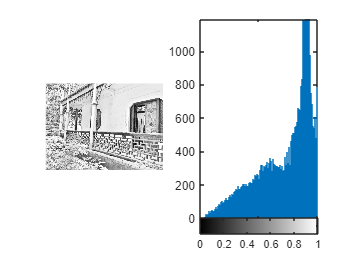

figure, subtitle('alpha=0.9'), subplot(1,2,1), imshow(vnew1);
subplot(1,2,2), imhist(vnew1);

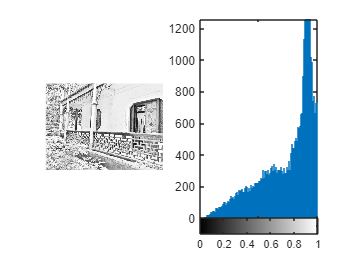


alpha2 = 0.7;
k2 = alpha2 * sum(s1(:)) / (row * col);
vnew2 = v1 * (1 + k2) ./ (max(v1, imggaus) + k2);
figure, subtitle('alpha=0.7'), subplot(1,2,1), imshow(vnew2);
subplot(1,2,2), imhist(vnew2);

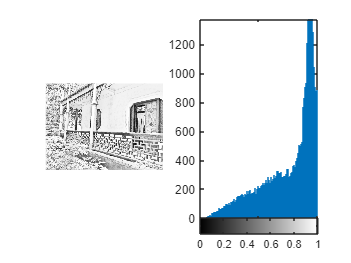


alpha3 = 0.5;
k3 = alpha3 * sum(s1(:)) / (row * col);
vnew3 = v1 * (1 + k3) ./ (max(v1, imggaus) + k3);
figure, subtitle('alpha=0.5'), subplot(1,2,1), imshow(vnew3);
subplot(1,2,2), imhist(vnew3);

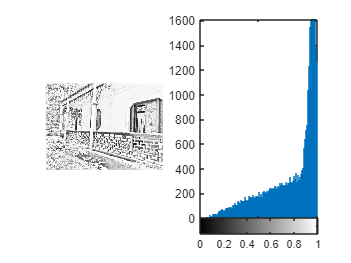


alpha4 = 0.3;
k4 = alpha4 * sum(s1(:)) / (row * col);
vnew4 = v1 * (1 + k4) ./ (max(v1, imggaus) + k4);
figure, subtitle('alpha=0.3'), subplot(1,2,1), imshow(vnew4);
subplot(1,2,2), imhist(vnew4);

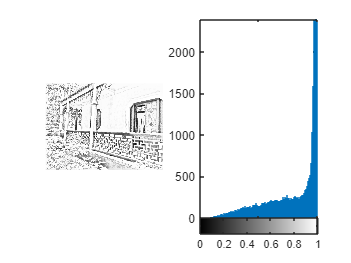


alpha5 = 0.1;
k5 = alpha5 * sum(s1(:)) / (row * col);
vnew5 = v1 * (1 + k5) ./ (max(v1, imggaus) + k5);
figure, subtitle('alpha=0.1'), subplot(1,2,1), imshow(vnew5);
subplot(1,2,2), imhist(vnew5);

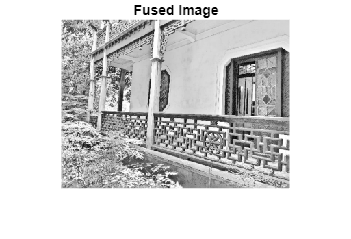


% Section 5: Eigenvalue Analysis and Weight Calculation
X1 = v1(:)';
X2 = vnew5(:)';
X = [X1 X2];
C = cov(X1, X2);
[V, D] = eig(C);
diagD = diag(D);
if diagD(1) > diagD(2)
    V1 = V(:,1);
else
    V1 = V(:,2);
end

w1 = V1(1) / (V1(1) + V1(2));
w2 = V1(2) / (V1(1) + V1(2));

F = w1 * v1 + w2 * vnew5;
figure, imshow(F), title('Fused Image')

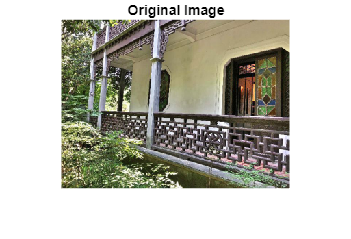


% Section 6: Final Image Composition and Display
out1(:,:,1) = h1;
out1(:,:,2) = s1;
out1(:,:,3) = F;
Out = hsv2rgb(out1);
figure, imshow(im), title('Original Image')

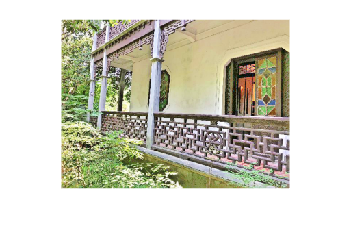

figure, imshow(Out)